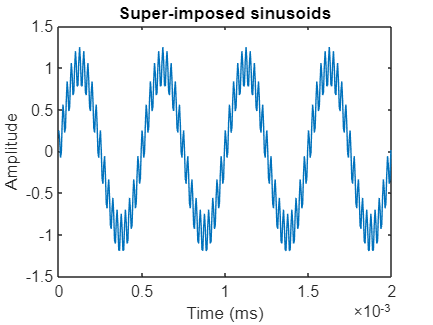

% Set the parameters
fs = 1/(5*10^(-6));        
fr1 = 2000;         
fr2 = 40000;
duration = 2*10^(-3);

% Generate the time vector
t = 0:1/fs:duration-1/fs;

% Generate waves
f1 = sin(2*pi*fr1*t);
f2 = 0.25*cos(2*pi*fr2*t);
yt = f1 + f2;


% Plot time domain
plot(t, yt);
xlabel('Time (ms)');
ylabel('Amplitude');
title('Super-imposed sinusoids');

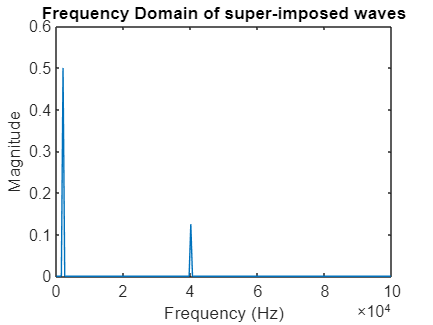


% Compute the Fourier Transform
Yw = abs(fft(yt))/length(yt);

% Generate the frequency vector
f_axis = linspace(0, fs, length(yt));

% Plot the frequency domain
plot(f_axis(1:length(yt)/2), Yw(1:length(yt)/2));
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain of super-imposed waves');

y=sawtooth(2*pi*f*t,0.5)